# Plotting with `datetime` Variables

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

EPL = readtable("../data/EPLtable_1.csv")

EPL = 20×5 table
              Team              Points    GoalDifference             Manager             ManagerHireDate
    ________________________    ______    ______________    _________________________    _______________

    {'Leicester City'      }      81            32          {'Claudio Ranieri'      }      07/13/2015   
    {'Arsenal'             }      71            29          {'Arsène Wenger'        }      10/01/1996   
    {'Tottenham Hotspur'   }      70            34          {'Mauricio Pochettino'  }      05/27/2014   
    {'Manchester City'     }      66            30          {'Manuel Pellegrini'    }      06/14/2013   
    {'Manchester United'   }      66            14          {'Louis van Gaal'       }      07/14/2014   
    {'Southampton'         }      63            18          {'Ronald Koeman' 

EPL(1:4, :)

ans = 4×5 table
            Team             Points    GoalDifference            Manager            ManagerHireDate
    _____________________    ______    ______________    _______________________    _______________

    {'Leicester City'   }      81            32          {'Claudio Ranieri'    }      07/13/2015   
    {'Arsenal'          }      71            29          {'Arsène Wenger'      }      10/01/1996   
    {'Tottenham Hotspur'}      70            34          {'Mauricio Pochettino'}      05/27/2014   
    {'Manchester City'  }      66            30          {'Manuel Pellegrini'  }      06/14/2013   


EPL.ManagerHireDate(1:4)

ans = 4×1 datetime array
   07/13/2015
   10/01/1996
   05/27/2014
   06/14/2013


## Task 1

EPL = sortrows(EPL, "ManagerHireDate")

EPL = 20×5 table
              Team              Points    GoalDifference             Manager             ManagerHireDate
    ________________________    ______    ______________    _________________________    _______________

    {'Arsenal'             }      71            29          {'Arsène Wenger'        }      10/01/1996   
    {'Bournemouth'         }      42           -22          {'Eddie Howe'           }      10/12/2012   
    {'Stoke City'          }      51           -14          {'Mark Hughes'          }      05/30/2013   
    {'Manchester City'     }      66            30          {'Manuel Pellegrini'    }      06/14/2013   
    {'Tottenham Hotspur'   }      70            34          {'Mauricio Pochettino'  }      05/27/2014   
    {'Southampton'         }      63            18          {'Ronald Koeman' 

## Task 2

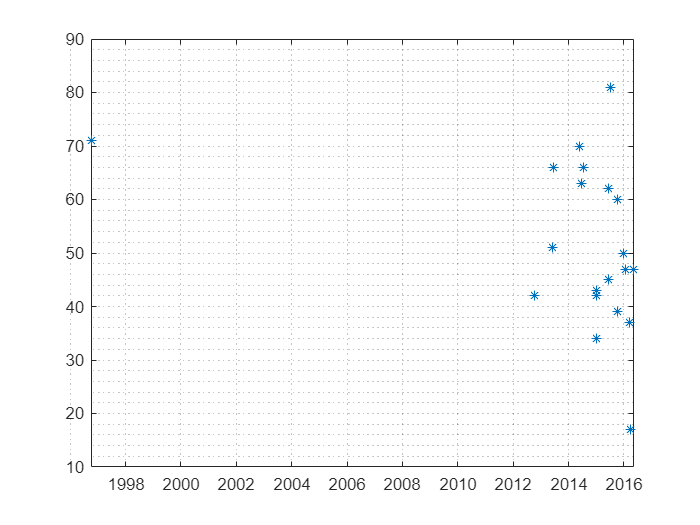

plot(EPL.ManagerHireDate, EPL.Points, "*")
grid minor

## Task 3

xMin = datetime(2012, 7, 1)

xMin = datetime
   01-Jul-2012


xMax = datetime(2016, 7, 1)

xMax = datetime
   01-Jul-2016


## Task 4

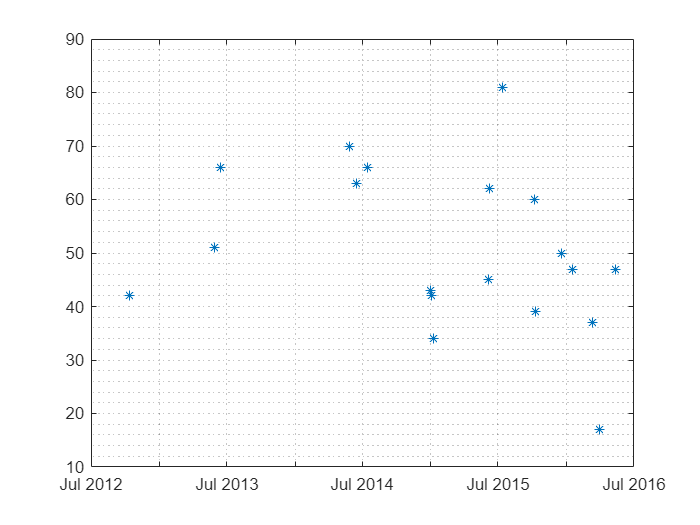

xlim([xMin, xMax])